# Plot the efficient frontiers for MVO and Robust MVO

## Load the parameters

load("All_returns.mat")
load("Xmkt.mat")
load("Xmvo.mat")
load("Xrobust_90.mat")
load("Xrobust_95.mat")
load("Xrp.mat")
load("R_oct.mat")
load("Q.mat")

mu = mean(returns);

## MVO frontiers

### Find minimum variance point to estimate the range for lambda

H = Q;
c = zeros(20,1);
A = []; % find minimum variance point (mvp) using no contraint for return
b = [];
e = ones(20,1);
Aeq = e';
beq = [1];

% minimum variance point with short selling
Wmvp = quadprog(H, c, A, b, Aeq, beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Wmvp =    -0.0265
   -0.0061
    0.1195
   -0.0686
    0.0597
    0.2288
    0.2809
    0.0020
    0.1660
   -0.1251


#### Estimated MVO frontier

weights = [];
SDmvo = [];

%estimated return 
Rmvo_e = [];

%actual return;
Rmvo_a = [];

f = -mu';
A = [];
b = [];
e = ones(20,1);
Aeq = e';
beq = [1];

Lambda =logspace(log10(10), log10(10^4), 20)

Lambda = 	1.0e+04 *

    0.0010    0.0014    0.0021    0.0030    0.0043    0.0062    0.0089    0.0127    0.0183    0.0264    0.0379    0.0546    0.0785    0.1129    0.1624    0.2336    0.3360    0.4833    0.6952    1.0000


#### Estimated and Actual frontier

for L = Lambda
    H = 2*L*Q;
    w = quadprog(H,f,A,b,Aeq,beq);  
    weights = [weights, w];
    SDmvo(end + 1) = sqrt(w'*Q*w);
    Rmvo_e(end + 1) = mu*w;
    Rmvo_a(end + 1) = R_oct*w;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### True frontier

weights_t = [];
SDmvo_t = [];

%true return
Rmvo_t = [];

f_t = -R_oct';

for L = Lambda(end-12:end)
    H = 2*L*Q;
    w = quadprog(H,f_t,A,b,Aeq,beq);  
    weights_t = [weights_t, w];
    SDmvo_t(end + 1) = sqrt(w'*Q*w);
    Rmvo_t(end + 1) = R_oct*w;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

## Robust MVO frontier

theta = (1/45)*diag(diag(Q));
x0 = zeros(1,20);

#### 95% confidence level (estimated and actual frontier)

efc_95 = sqrt(chi2inv(0.95,20))

efc_95 = 5.6045

SDrobust_95 = [];
Rrobust_e_95 = [];
Rrobust_a_95 = [];

for L = Lambda
    fun_95 = @(x)L*x*Q*x' - mu*x' + efc_95*sqrt(x*theta*x');
    w = fmincon(fun_95,x0,A,b,Aeq,beq)     
    SDrobust_95(end + 1) = sqrt(w*Q*w');
    Rrobust_e_95(end + 1) = mu*w';
    Rrobust_a_95(end + 1) = R_oct*w';
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0197    0.0299    0.0598    0.0731    0.1389    0.1443    0.1211   -0.0402    0.0547    0.0290    0.0162    0.0314   -0.0023    0.1261    0.0537    0.0390    0.0827    0.0262    0.0029    0.0331



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0213    0.0287    0.0648    0.0582    0.1309    0.1453    0.1381   -0.0409    0.0581    0.0261    0.0104    0.0288   -0.0008    0.1298    0.0532    0.0383    0.0861    0.0232    0.0010    0.0420



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0233    0.0273    0.0715    0.0410    0.1214    0.1469    0.1573   -0.0417    0.0624    0.0220    0.0039    0.0256   -0.0000    0.1321    0.0537    0.0380    0.0894    0.0206   -0.0005    0.0525



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0255    0.0255    0.0798    0.0219    0.1104    0.1495    0.1775   -0.0418    0.0677    0.0164   -0.0028    0.0218   -0.0001    0.1319    0.0554    0.0379    0.0925    0.0189   -0.0012    0.0643



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0277    0.0231    0.0893    0.0022    0.0988    0.1536    0.1970   -0.0404    0.0739    0.0088   -0.0093    0.0176   -0.0011    0.1288    0.0585    0.0376    0.0949    0.0185   -0.0006    0.0765



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0295    0.0200    0.0989   -0.0163    0.0877    0.1596    0.2144   -0.0374    0.0811   -0.0010   -0.0151    0.0134   -0.0028    0.1227    0.0628    0.0366    0.0960    0.0196    0.0011    0.0882



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0307    0.0163    0.1075   -0.0322    0.0782    0.1673    0.2291   -0.0328    0.0894   -0.0131   -0.0199    0.0093   -0.0047    0.1141    0.0679    0.0349    0.0957    0.0217    0.0034    0.0985



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0313    0.0124    0.1141   -0.0445    0.0709    0.1764    0.2411   -0.0275    0.0987   -0.0272   -0.0235    0.0056   -0.0065    0.1039    0.0733    0.0325    0.0939    0.0247    0.0057    0.1073



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0314    0.0087    0.1184   -0.0533    0.0657    0.1859    0.2508   -0.0219    0.1088   -0.0425   -0.0260    0.0022   -0.0080    0.0934    0.0783    0.0299    0.0909    0.0282    0.0076    0.1145



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0310    0.0052    0.1208   -0.0592    0.0624    0.1951    0.2586   -0.0167    0.1191   -0.0580   -0.0277   -0.0009   -0.0093    0.0835    0.0825    0.0274    0.0873    0.0319    0.0089    0.1202



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0304    0.0024    0.1218   -0.0629    0.0605    0.2032    0.2646   -0.0122    0.1289   -0.0725   -0.0287   -0.0036   -0.0102    0.0750    0.0858    0.0251    0.0835    0.0353    0.0098    0.1246



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0296    0.0001    0.1219   -0.0652    0.0596    0.2099    0.2692   -0.0085    0.1376   -0.0851   -0.0292   -0.0059   -0.0110    0.0683    0.0881    0.0233    0.0800    0.0384    0.0103    0.1279



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0289   -0.0016    0.1216   -0.0665    0.0592    0.2151    0.2726   -0.0057    0.1448   -0.0955   -0.0295   -0.0078   -0.0116    0.0631    0.0897    0.0220    0.0771    0.0409    0.0106    0.1304



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0283   -0.0029    0.1212   -0.0673    0.0591    0.2190    0.2750   -0.0035    0.1505   -0.1036   -0.0296   -0.0092   -0.0121    0.0593    0.0908    0.0209    0.0747    0.0429    0.0108    0.1322



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0278   -0.0038    0.1208   -0.0678    0.0592    0.2218    0.2768   -0.0019    0.1549   -0.1097   -0.0297   -0.0103   -0.0124    0.0566    0.0915    0.0202    0.0729    0.0443    0.0109    0.1335



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0274   -0.0045    0.1205   -0.0681    0.0593    0.2239    0.2780   -0.0008    0.1581   -0.1141   -0.0297   -0.0111   -0.0127    0.0546    0.0920    0.0197    0.0716    0.0454    0.0110    0.1344



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0272   -0.0050    0.1203   -0.0683    0.0594    0.2253    0.2789    0.0000    0.1604   -0.1174   -0.0297   -0.0117   -0.0129    0.0533    0.0923    0.0193    0.0706    0.0462    0.0110    0.1351



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0270   -0.0053    0.1201   -0.0684    0.0594    0.2264    0.2795    0.0006    0.1621   -0.1197   -0.0297   -0.0121   -0.0130    0.0523    0.0925    0.0191    0.0699    0.0468    0.0110    0.1355



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0268   -0.0055    0.1199   -0.0685    0.0595    0.2271    0.2799    0.0010    0.1632   -0.1213   -0.0297   -0.0124   -0.0131    0.0516    0.0927    0.0189    0.0694    0.0472    0.0110    0.1358



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0267   -0.0057    0.1198   -0.0685    0.0595    0.2276    0.2802    0.0013    0.1641   -0.1225   -0.0297   -0.0126   -0.0131    0.0512    0.0928    0.0188    0.0691    0.0475    0.0110    0.1361


#### 90% confidence level (estimated and actual frontier)

efc_90 = sqrt(chi2inv(0.90,20))

efc_90 = 5.3303

SDrobust_90 = [];
Rrobust_e_90 = [];
Rrobust_a_90 = [];

for L = Lambda
    fun_90 = @(x)L*x*Q*x' - mu*x' + efc_90*sqrt(x*theta*x');
    w = fmincon(fun_90,x0,A,b,Aeq,beq)     
    SDrobust_90(end + 1) = sqrt(w*Q*w');
    Rrobust_e_90(end + 1) = mu*w';
    Rrobust_a_90(end + 1) = R_oct*w';
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0212    0.0298    0.0593    0.0744    0.1400    0.1462    0.1241   -0.0436    0.0570    0.0297    0.0167    0.0306   -0.0048    0.1246    0.0548    0.0406    0.0818    0.0258    0.0004    0.0337



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0226    0.0285    0.0648    0.0587    0.1313    0.1470    0.1415   -0.0440    0.0606    0.0267    0.0106    0.0278   -0.0031    0.1283    0.0543    0.0398    0.0853    0.0228   -0.0011    0.0429



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0245    0.0270    0.0719    0.0408    0.1212    0.1485    0.1608   -0.0444    0.0650    0.0224    0.0039    0.0245   -0.0022    0.1304    0.0548    0.0393    0.0888    0.0204   -0.0023    0.0537



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0266    0.0252    0.0806    0.0212    0.1097    0.1510    0.1809   -0.0440    0.0703    0.0164   -0.0030    0.0206   -0.0021    0.1301    0.0566    0.0391    0.0919    0.0190   -0.0025    0.0656



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0285    0.0226    0.0904    0.0012    0.0978    0.1552    0.2001   -0.0422    0.0766    0.0085   -0.0096    0.0164   -0.0030    0.1268    0.0598    0.0385    0.0941    0.0189   -0.0015    0.0778



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0301    0.0194    0.1002   -0.0173    0.0866    0.1612    0.2170   -0.0386    0.0839   -0.0018   -0.0154    0.0121   -0.0045    0.1206    0.0641    0.0373    0.0952    0.0202    0.0006    0.0893



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0311    0.0157    0.1086   -0.0330    0.0772    0.1690    0.2311   -0.0337    0.0921   -0.0143   -0.0201    0.0081   -0.0062    0.1120    0.0692    0.0353    0.0948    0.0225    0.0031    0.0996



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0315    0.0118    0.1150   -0.0450    0.0700    0.1781    0.2427   -0.0280    0.1013   -0.0287   -0.0236    0.0045   -0.0078    0.1020    0.0744    0.0328    0.0929    0.0256    0.0055    0.1082



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0314    0.0081    0.1191   -0.0536    0.0650    0.1875    0.2520   -0.0222    0.1113   -0.0443   -0.0261    0.0012   -0.0091    0.0916    0.0793    0.0300    0.0899    0.0291    0.0075    0.1152



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0310    0.0048    0.1212   -0.0593    0.0619    0.1965    0.2595   -0.0169    0.1214   -0.0598   -0.0277   -0.0017   -0.0101    0.0821    0.0833    0.0274    0.0864    0.0326    0.0089    0.1208



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0303    0.0020    0.1220   -0.0629    0.0602    0.2043    0.2653   -0.0123    0.1309   -0.0742   -0.0286   -0.0043   -0.0109    0.0739    0.0863    0.0251    0.0827    0.0360    0.0097    0.1250



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0295   -0.0002    0.1220   -0.0651    0.0594    0.2107    0.2697   -0.0086    0.1392   -0.0866   -0.0292   -0.0065   -0.0115    0.0674    0.0885    0.0233    0.0793    0.0389    0.0103    0.1283



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0288   -0.0019    0.1217   -0.0664    0.0591    0.2157    0.2729   -0.0057    0.1461   -0.0966   -0.0295   -0.0082   -0.0120    0.0625    0.0900    0.0219    0.0765    0.0413    0.0106    0.1306



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0282   -0.0031    0.1213   -0.0672    0.0591    0.2194    0.2753   -0.0035    0.1515   -0.1045   -0.0296   -0.0096   -0.0124    0.0589    0.0910    0.0209    0.0743    0.0432    0.0108    0.1324



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0277   -0.0040    0.1209   -0.0677    0.0591    0.2222    0.2769   -0.0019    0.1556   -0.1103   -0.0297   -0.0106   -0.0126    0.0563    0.0916    0.0202    0.0726    0.0446    0.0109    0.1336



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0274   -0.0046    0.1205   -0.0680    0.0592    0.2241    0.2781   -0.0008    0.1586   -0.1146   -0.0297   -0.0113   -0.0128    0.0544    0.0921    0.0197    0.0713    0.0456    0.0109    0.1345



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0271   -0.0050    0.1203   -0.0682    0.0593    0.2255    0.2790    0.0000    0.1608   -0.1177   -0.0297   -0.0118   -0.0130    0.0531    0.0924    0.0193    0.0704    0.0464    0.0110    0.1351



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0269   -0.0053    0.1201   -0.0684    0.0594    0.2265    0.2796    0.0006    0.1623   -0.1199   -0.0297   -0.0122   -0.0131    0.0522    0.0926    0.0191    0.0698    0.0469    0.0110    0.1356



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0268   -0.0056    0.1199   -0.0685    0.0595    0.2272    0.2800    0.0010    0.1634   -0.1215   -0.0297   -0.0125   -0.0131    0.0516    0.0927    0.0189    0.0693    0.0473    0.0110    0.1359



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


w =    -0.0267   -0.0057    0.1198   -0.0685    0.0595    0.2277    0.2803    0.0013    0.1642   -0.1226   -0.0297   -0.0127   -0.0132    0.0511    0.0928    0.0188    0.0690    0.0475    0.0110    0.1361


## Plot frontiers

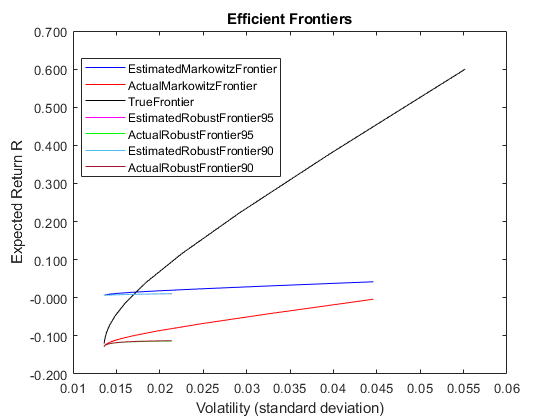

%plot efficient frontier with short selling and without short selling
figure
plot(SDmvo, Rmvo_e,'b-')
hold on 
plot(SDmvo, Rmvo_a, 'r-' )
plot(SDmvo_t, Rmvo_t, 'k-' )
plot(SDrobust_95, Rrobust_e_95, 'm-' )
plot(SDrobust_95, Rrobust_a_95, 'g-' )
plot(SDrobust_90, Rrobust_e_90  )
plot(SDrobust_90, Rrobust_a_90 )
hold off
legend({'EstimatedMarkowitzFrontier', 'ActualMarkowitzFrontier', 'TrueFrontier', 'EstimatedRobustFrontier95', 'ActualRobustFrontier95', 'EstimatedRobustFrontier90', 'ActualRobustFrontier90'}, 'Location','best')
title('Efficient Frontiers')
ylabel('Expected Return R')
xlabel('Volatility (standard deviation)')
ytickformat('%.3f')
ax = gca;
ax.YAxis.Exponent = 0;